clc; clear; close all;

%% PoleTest_Voltage.m
% Pole placement test for rotary inverted pendulum with VOLTAGE as input.
%
% Original torque-input model:
%       x_dot = A*x + B_tau*tau_m
%
% DC motor model:
%       tau_m = kt*i
%       V = Rm*i + ke*omega_m
%
% Assuming motor angular velocity omega_m = dtheta_1:
%       tau_m = (kt/Rm)*V - (kt*ke/Rm)*dtheta_1
%
% Therefore:
%       x_dot = A_v*x + B_v*V
%
% where:
%       A_v = A - B_tau*(kt*ke/Rm)*[0 0 1 0]
%       B_v = B_tau*(kt/Rm)

%% 1) Torque-input linearized system matrices
A_tau = [0 0 1 0;
         0 0 0 1;
         0 16.5917 0 0;
         0 105.5970 0 0];

B_tau = [0;
         0;
         1475.6369;
         1173.3223];

C = [0 1 0 0];     % output = theta_2
D = 0;

%% 2) DC motor parameters
% Estimated and assumed values - subject to change
Rm = 8.4;          % [Ohm] Motor terminal resistance
kt = 0.042;        % [N*m/A] Torque constant
ke = 0.042;        % [V/(rad/s)] Back-EMF constant

% Motor voltage limit for simulation
V_limit = 10;      % [V] practical command voltage limit - same for LQR Test

%% 3) Convert from torque input to voltage input
speed_selector = [0 0 1 0];   % selects dtheta_1 from x

A_v = A_tau - B_tau*(kt*ke/Rm)*speed_selector;
B_v = B_tau*(kt/Rm);

sys_v_ol = ss(A_v,B_v,C,D);

disp('Voltage-input A matrix:')

Voltage-input A matrix:


disp(A_v)

         0         0    1.0000         0
         0         0         0    1.0000
         0   16.5917   -0.3099         0
         0  105.5970   -0.2464         0




disp('Voltage-input B matrix:')

Voltage-input B matrix:


disp(B_v)

         0
         0
    7.3782
    5.8666




%% 4) Check controllability
Co = ctrb(A_v,B_v);
rank_Co = rank(Co);

disp('Controllability matrix rank:')

Controllability matrix rank:


disp(rank_Co)

     4




if rank_Co == size(A_v,1)
    disp('Voltage-input system is controllable -> pole placement can be used.')
else
    error('Voltage-input system is NOT controllable. Pole placement cannot be used directly.')
end

Voltage-input system is controllable -> pole placement can be used.



%% 5) Open-loop poles
disp('Open-loop poles for voltage-input model:')

Open-loop poles for voltage-input model:


disp(eig(A_v))

         0
   10.2572
  -10.2959
   -0.2711




%% 6) Choose desired closed-loop poles
% Start with moderate real poles.
% More negative poles = faster response, but larger voltage command.
p_des = [-7 -8 -9 -10];

%% 7) Compute state feedback gain
% MATLAB convention:
%       V = -K*x
K = place(A_v,B_v,p_des);

disp('State feedback gain K for voltage input:')

State feedback gain K for voltage input:


disp(K)

   -7.3924  100.7634   -3.5827   10.2486




%% 8) Closed-loop system
A_cl = A_v - B_v*K;
sys_cl = ss(A_cl,B_v,C,D);

cl_poles = eig(A_cl);

disp('Closed-loop poles:')

Closed-loop poles:


disp(cl_poles)

  -10.0000
   -9.0000
   -8.0000
   -7.0000




if all(real(cl_poles) < 0)
    disp('Closed-loop system is asymptotically stable.')
else
    disp('Closed-loop system is NOT asymptotically stable.')
end

Closed-loop system is asymptotically stable.



%% 9) Damping information
disp('Damping information:')

Damping information:


damp(sys_cl)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -7.00e+00     1.00e+00       7.00e+00         1.43e-01    
 -8.00e+00     1.00e+00       8.00e+00         1.25e-01    
 -9.00e+00     1.00e+00       9.00e+00         1.11e-01    
 -1.00e+01     1.00e+00       1.00e+01         1.00e-01    


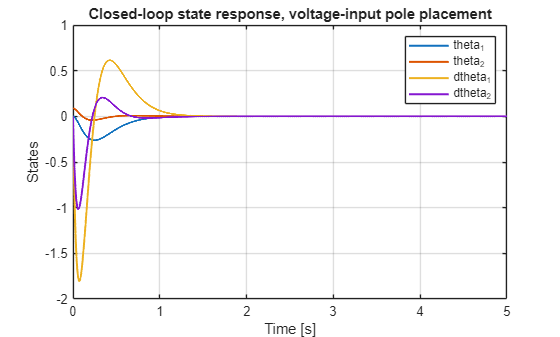


%% 10) Simulate initial-condition response
x0 = [0; deg2rad(5); 0; 0];   % initial pendulum angle deviation
t = 0:0.001:5;

[y,t,x] = initial(sys_cl,x0,t);

figure;
plot(t, x(:,1), 'LineWidth', 1.5); hold on;
plot(t, x(:,2), 'LineWidth', 1.5);
plot(t, x(:,3), 'LineWidth', 1.5);
plot(t, x(:,4), 'LineWidth', 1.5);
grid on;
xlabel('Time [s]')
ylabel('States')
legend('theta_1','theta_2','dtheta_1','dtheta_2')
title('Closed-loop state response, voltage-input pole placement')

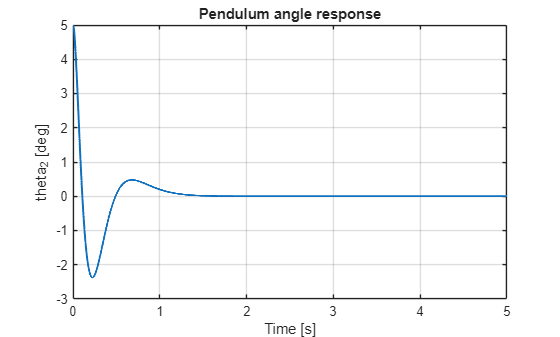


figure;
plot(t, rad2deg(x(:,2)), 'LineWidth', 1.5);
grid on;
xlabel('Time [s]')
ylabel('theta_2 [deg]')
title('Pendulum angle response')

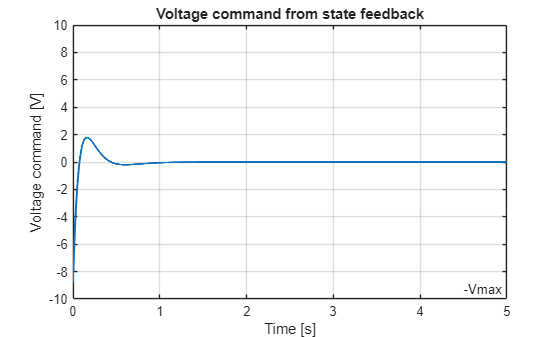


%% 11) Compute voltage command V(t) = -K*x(t)
V_cmd = zeros(length(t),1);

for i = 1:length(t)
    V_cmd(i) = -K*x(i,:)';
end

figure;
plot(t, V_cmd, 'LineWidth', 1.5); hold on;
yline(V_limit, '--', 'Vmax');
yline(-V_limit, '--', '-Vmax');
grid on;
xlabel('Time [s]')
ylabel('Voltage command [V]')
title('Voltage command from state feedback')

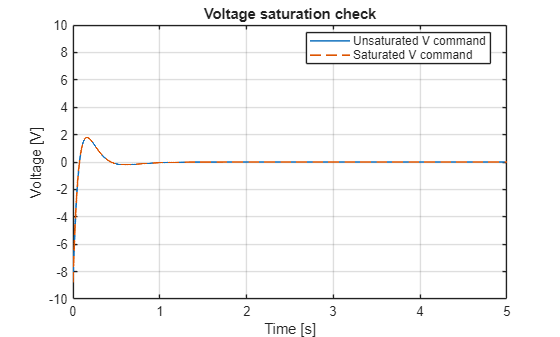


%% 12) Saturated voltage command check
V_cmd_sat = min(max(V_cmd, -V_limit), V_limit);

figure;
plot(t, V_cmd, 'LineWidth', 1.2); hold on;
plot(t, V_cmd_sat, '--', 'LineWidth', 1.2);
yline(V_limit, '--');
yline(-V_limit, '--');
grid on;
xlabel('Time [s]')
ylabel('Voltage [V]')
legend('Unsaturated V command','Saturated V command','Location','best')
title('Voltage saturation check')


%% 13) Performance measures
theta2_deg = rad2deg(x(:,2));

max_angle = max(abs(theta2_deg));
max_voltage = max(abs(V_cmd));
max_voltage_sat = max(abs(V_cmd_sat));

% Approximate settling time:
% first time theta_2 enters 2% band and stays there.
theta_ref = abs(rad2deg(x0(2)));
tol = 0.02 * theta_ref;

settling_time = NaN;
for i = 1:length(t)
    if all(abs(theta2_deg(i:end)) <= tol)
        settling_time = t(i);
        break;
    end
end

disp('Performance measures:')

Performance measures:


fprintf('Maximum pendulum angle deviation: %.3f deg\n', max_angle);

Maximum pendulum angle deviation: 5.000 deg


fprintf('Maximum voltage command: %.3f V\n', max_voltage);

Maximum voltage command: 8.793 V


fprintf('Maximum saturated voltage command: %.3f V\n', max_voltage_sat);

Maximum saturated voltage command: 8.793 V


fprintf('Approx. settling time: %.3f s\n', settling_time);

Approx. settling time: 1.149 s



if max_voltage <= V_limit
    disp('Voltage command stays within the selected voltage limit.')
else
    disp('Voltage command exceeds the selected voltage limit. Choose slower poles or use LQR with higher R.')
end

Voltage command stays within the selected voltage limit.



%% 14) Optional: compare several pole sets automatically
pole_sets = {
    [-6 -7 -8 -9]
    [-7 -8 -9 -10]
    [-8 -9 -10 -11]
    [-12 -13 -14 -15]
    [-13 -14 -15 -16]
};

results = [];

for kset = 1:length(pole_sets)
    p_test = pole_sets{kset};

    K_test = place(A_v,B_v,p_test);
    A_test = A_v - B_v*K_test;
    sys_test = ss(A_test,B_v,C,D);

    [~,t_test,x_test] = initial(sys_test,x0,t);

    V_test = zeros(length(t_test),1);
    for i = 1:length(t_test)
        V_test(i) = -K_test*x_test(i,:)';
    end

    theta2_test_deg = rad2deg(x_test(:,2));
    max_angle_test = max(abs(theta2_test_deg));
    max_voltage_test = max(abs(V_test));

    settling_time_test = NaN;
    for i = 1:length(t_test)
        if all(abs(theta2_test_deg(i:end)) <= tol)
            settling_time_test = t_test(i);
            break;
        end
    end

    stable_test = all(real(eig(A_test)) < 0);

    % Simple score: lower is better.
    % Voltage is weighted strongly because the actuator limit matters.
    if isnan(settling_time_test)
        score = inf;
    else
        score = settling_time_test + 0.05*max_voltage_test + 0.02*max_angle_test;
    end

    results = [results;
        kset, stable_test, settling_time_test, max_angle_test, max_voltage_test, score];
end

disp('Pole set comparison:')

Pole set comparison:


disp('Columns: set#, stable, settling_time, max_angle_deg, max_voltage_V, score')

Columns: set#, stable, settling_time, max_angle_deg, max_voltage_V, score


disp(results)

    1.0000    1.0000    1.2930    5.0000    7.0407    1.7450
    2.0000    1.0000    1.1490    5.0000    8.7933    1.6887
    3.0000    1.0000    1.0370    5.0000   10.8634    1.6802
    4.0000    1.0000    0.7580    5.0000   23.0732    2.0117
    5.0000    1.0000    0.7130    5.0000   27.3301    2.1795




% Find best finite score
finite_scores = results(:,6);
[best_score,best_idx] = min(finite_scores);

if isfinite(best_score)
    best_set_number = results(best_idx,1);
    disp('Best pole set according to simple score:')
    disp(pole_sets{best_set_number})
else
    disp('No finite best pole set found.')
end

Best pole set according to simple score:


    -8    -9   -10   -11

